# Least Square Classification and Fisher Linear Discriminant

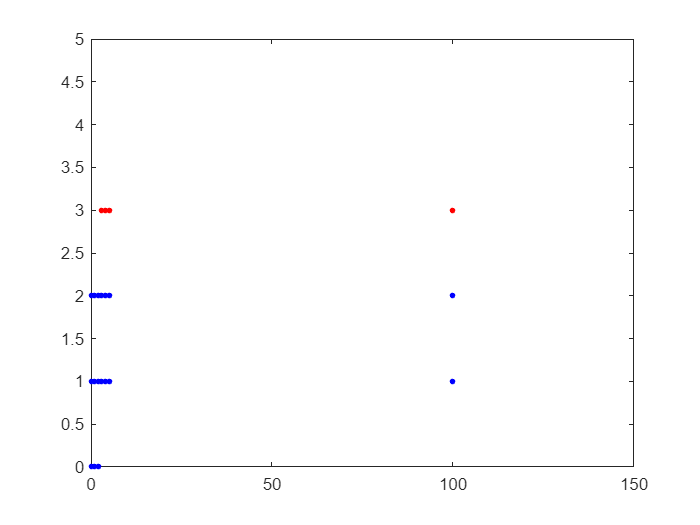

clear;clc;

C1 = [[0 0]', [1 0]', [2 0]', [0 1]', [1 1]', [2 1]', [3 1]', [4 1]', [5 1]', [100 1]', [0 2]', [1 2]', [2 2]', [3 2]', [4 2]', [5 2]', [100 2]'];
C2 = [[3 3]', [4 3]', [5 3]', [100 3]'];

plot(C1(1,:),C1(2,:),'.','MarkerSize',10,'Color','blue');
axis([0 150 0 5]);
hold on;
plot(C2(1,:),C2(2,:),'.','MarkerSize',10,'Color','red');

% grid on;

## Least Square Classification

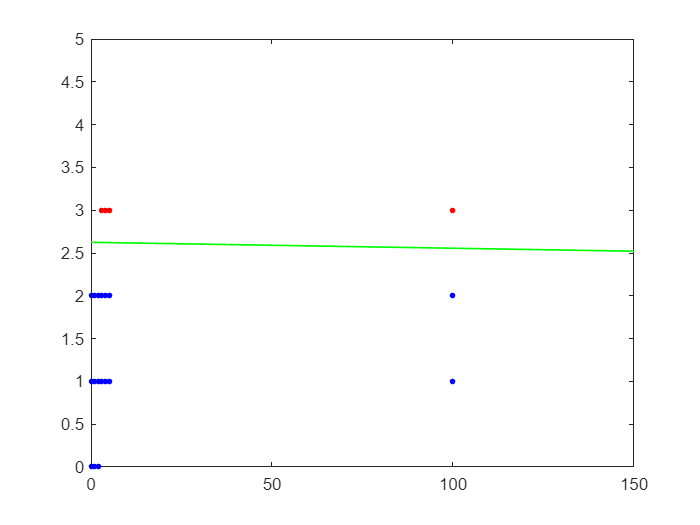

X = [C1 C2];
Xaug = [ones(1,size(X,2));X]';

T = [repmat([1 0], size(C1,2), 1); repmat([0 1], size(C2,2), 1)];

Waug = ((Xaug'*Xaug)\Xaug')*T;
Wdec = Waug(:,1) - Waug(:,2);

[~, arg] = max(Xaug*Waug, [], 2);

dec_boundary = @(x) -(Wdec(2)/Wdec(3))*x - (Wdec(1)/Wdec(3));
plot(0:150,dec_boundary(0:150), '-', "Color","green", "LineWidth",1);

## Fisher's Linear Discriminant

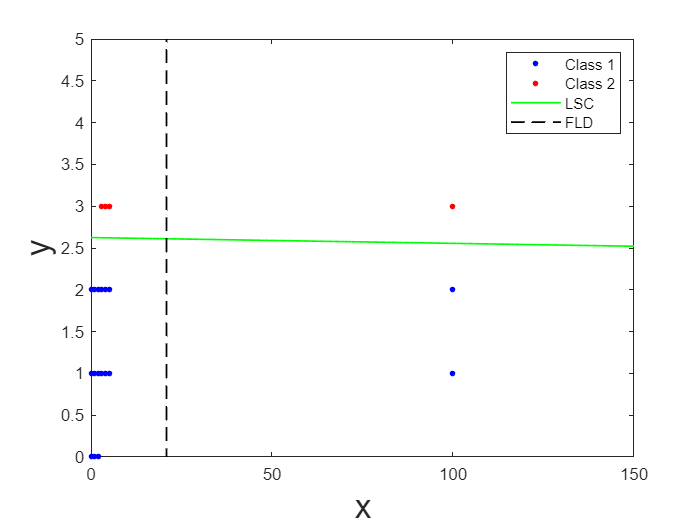

m1 = mean(C1, 2);
v1 = zeros(size(C1,1), size(C1,1));
for i = 1:size(C1,2)
    x = C1(:,i);
    v1 = v1 + (x-m1)*(x-m1)';
end

m2 = mean(C2, 2);
v2 = zeros(size(C2,1), size(C2,1));
for i = 1:size(C2,2)
    x = C2(:,i);
    v2 = v2 + (x-m2)*(x-m2)';
end

Sw = v1+v2;
W = Sw\(m1-m2);
% W = W/norm(W);

m = 0.5*(m1+m2);
% c = m(2)-(-W(1)/W(2))*m(1);
% 
% dec_boundary = @(x) (-W(1)/W(2))*x + c;
% plot(0:150,dec_boundary(0:150), '-', "Color","black", "LineWidth",1);
c = m(2)-(W(2)/W(1))*m(1);
discriminant_line = @(x) (W(2)/W(1))*x + c;
plot(0:150,discriminant_line(0:150), '--', "Color","black", "LineWidth",1);
legend('Class 1', 'Class 2', 'LSC', 'FLD')
xlabel("x","FontSize",20); ylabel("y","FontSize",20);